clc;
clear all;
close all;

% Note: Interactive figure plotting is re-enabled as requested. 

% =======================================================
% --- 1. GLOBAL PARAMETERS ---
% =======================================================

% --- Define dataset paths (UPDATED TO RELATIVE PATHS) ---
imageFolder = '.\Saliva_Segmentation_dataset\Raw_images';
gtFolder    = '.\Saliva_Segmentation_dataset\Binary_masks'; 

% --- Model Parameters ---
NUM_TRAINING_IMAGES = 8;
TEST_IMAGE_START = 9;
NUM_TOTAL_TEST_IMAGES = 2; % Images 9 and 10
NUM_REGIONS_TO_KEEP = 4;    % Used only for calculating the GT-Center and Area Range in TRAINING
MIN_AREA_THRESHOLD = 20;    % Minimum area to be considered a component (General small component removal)

% --- Threshold Tuning Parameters ---
% Bias sweep for Precision optimization (Negative for permissive, Positive for strict)
thresholdBiases = -0.05:0.05:0.20; 

% --- Test Filtering Parameters (NEW) ---
% Fixed area bounds for filtering False Positives in the TESTING phase.
% Based on typical component size: Filter out small noise and massive background components.
FIXED_MIN_AREA_TEST = 50000; % Filter out small noise components
FIXED_MAX_AREA_TEST = 200000; % Filter out massive components (like the entire background)

% --- Storage for test results (Images 9 and 10) ---
P_test = zeros(1, NUM_TOTAL_TEST_IMAGES);
R_test = zeros(1, NUM_TOTAL_TEST_IMAGES);
D_test = zeros(1, NUM_TOTAL_TEST_IMAGES);
A_test = zeros(1, NUM_TOTAL_TEST_IMAGES); 

% --- Helper: robust GT loading to binary ---
toBinaryMask = @(X) logical(any(X(:,:,1:min(end,3)) > 0, 3));


% =======================================================
% --- 2. SEGMENTATION FUNCTION ---
% Includes two paths: Training (with filtering) and Testing (with simpler filter)
% =======================================================
function [P, R, D, A, mask, GT] = segmentImage(imgNum, thresholdBias, imageFolder, gtFolder, toBinaryMask, numRegions, minArea, isTraining, fixedMinArea, fixedMaxArea)
    
    % --- 1. Load Data and Pre-process ---
    fileName = fullfile(imageFolder, sprintf('%d.tif', imgNum));
    gtName   = fullfile(gtFolder, sprintf('%d.tif', imgNum));

    I  = imread(fileName);
    I = I(:,:,1:3); 
    L_test = 0.299*double(I(:,:,1)) + 0.587*double(I(:,:,2)) + 0.114*double(I(:,:,3));
    
    GTraw = imread(gtName);
    GT = imresize(toBinaryMask(GTraw), size(L_test), 'nearest');
    
    % --- Dynamic Area Range (Used in Training Filter ONLY) ---
    total_gt_area = sum(GT(:));
    target_area = total_gt_area / numRegions;
    minAreaRange = target_area * 0.50; 
    maxAreaRange = target_area * 1.50; 
    
    % --- PREPROCESSING STEP: CLAHE Normalization ---
    L_uint8 = uint8(L_test);
    L_enhanced = adapthisteq(L_uint8, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');
    
    % --- THRESHOLDING: Otsu's Threshold with Bias ---
    otsu_level = graythresh(L_enhanced); 
    final_level = otsu_level * (1 - thresholdBias); 
    final_level = max(0, min(1, final_level));
    
    mask_initial = imbinarize(L_enhanced, final_level);
    
    % ====================================================================
    % --- DECISION POINT: TRAINING (Filter) vs. TESTING (Filter) ---
    % ====================================================================
    if isTraining
        % --- TRAINING PATH: Applies the two-stage filtering for robust tuning ---

        % --- Calculate Dynamic Center ---
        CC_GT = bwconncomp(GT);
        stats_GT = regionprops(CC_GT, 'Centroid', 'Area');
        
        [~, sorted_idx_GT] = sort([stats_GT.Area], 'descend');
        numGTComponents = min(numRegions, length(sorted_idx_GT)); 
        
        if numGTComponents > 0
            selectedCentroids = cat(1, stats_GT(sorted_idx_GT(1:numGTComponents)).Centroid);
            center_x = mean(selectedCentroids(:,1));
            center_y = mean(selectedCentroids(:,2));
        else
            [rows, cols] = size(L_test);
            center_y = rows / 2;
            center_x = cols / 2;
        end
        
        % Label components in the Initial Mask
        CC = bwconncomp(mask_initial);
        stats = regionprops(CC, 'Centroid', 'Area');
        
        % --- FILTER STAGE 1: Area Plausibility (Dynamic Range) ---
        validIndices = find( ([stats.Area] >= minArea) & ...
                             ([stats.Area] >= minAreaRange) & ...
                             ([stats.Area] <= maxAreaRange) );
        
        if isempty(validIndices)
            mask = false(size(L_test));
        else
            % --- FILTER STAGE 2: Weighted Centrality Score ---
            eps_val = 1e-3; 
            distances = zeros(1, length(validIndices));
            areas = zeros(1, length(validIndices));

            for i = 1:length(validIndices)
                idx = validIndices(i);
                centroid = stats(idx).Centroid;
                distances(i) = sqrt((centroid(1) - center_x)^2 + (centroid(2) - center_y)^2);
                areas(i) = stats(idx).Area;
            end
            
            % Score: Area / (Distance + epsilon)
            scores = areas ./ (distances + eps_val);
            maxScore = max(scores);
            scoreThreshold = 0.5 * maxScore;

            highlyScoredIndices = validIndices(scores >= scoreThreshold);
            
            if isempty(highlyScoredIndices)
                mask = false(size(L_test)); 
            else
                mask = ismember(labelmatrix(CC), highlyScoredIndices);
            end
        end
        
    else 
        % --- TESTING PATH: Otsu's + Bias followed by FIXED Area Filter ---
        
        CC = bwconncomp(mask_initial);
        stats = regionprops(CC, 'Area');
        
        % Identify components that fall within the fixed area range
        validIndices = find( ([stats.Area] >= fixedMinArea) & ...
                             ([stats.Area] <= fixedMaxArea) );
        
        if isempty(validIndices)
            mask = false(size(L_test));
        else
            % Construct the mask using only the components that meet the fixed area bounds
            mask = ismember(labelmatrix(CC), validIndices);
        end
    end
    
    % --- Morphological Cleanup (Applied to both Training and Testing) ---
    SE = strel('disk', 3); 
    mask = imclose(mask, SE);

    % --- METRIC CALCULATION ---
    GT_vec = GT(:); Mask_vec = mask(:);
    
    TP = sum(Mask_vec & GT_vec); 
    FP = sum(Mask_vec & (~GT_vec)); 
    FN = sum((~Mask_vec) & GT_vec);
    TotalPixels = numel(GT_vec);
    TN = sum((~Mask_vec) & (~GT_vec)); 
    
    eps = 1e-6; 
    P = TP / (TP + FP + eps);
    R = TP / (TP + FN + eps);
    D = (2 * TP) / (2 * TP + FP + FN + eps);
    A = (TP + TN) / (TotalPixels + eps);
end


% =======================================================
% --- 3. TRAINING PHASE: Find Best Threshold Bias (Images 1-8) ---
% =======================================================
fprintf('--- 1. Training Phase: Finding Optimal Bias on Images 1-8 (Using GT-Centered, Weighted Filter) ---\n');

--- 1. Training Phase: Finding Optimal Bias on Images 1-8 (Using GT-Centered, Weighted Filter) ---



meanDice_sweep = zeros(1, length(thresholdBiases));

for b = 1:length(thresholdBiases)
    currentBias = thresholdBiases(b);
    dice_sum = 0;
    
    for imgNum = 1:NUM_TRAINING_IMAGES % Loop up to Image 8
        % isTraining is true for this phase
        % NOTE: fixedMinArea and fixedMaxArea are ignored in the training path, 
        % but we must pass placeholder values (0, inf) to match the function signature.
        [~, ~, D, ~, ~] = segmentImage(imgNum, currentBias, imageFolder, gtFolder, toBinaryMask, NUM_REGIONS_TO_KEEP, MIN_AREA_THRESHOLD, true, 0, inf);
        dice_sum = dice_sum + D;
    end
    
    meanDice_sweep(b) = dice_sum / NUM_TRAINING_IMAGES;
    fprintf('  Bias: %.2f | Mean Dice (1-8): %.4f\n', currentBias, meanDice_sweep(b));
end

  Bias: -0.05 | Mean Dice (1-8): 0.8148
  Bias: 0.00 | Mean Dice (1-8): 0.7298
  Bias: 0.05 | Mean Dice (1-8): 0.6243
  Bias: 0.10 | Mean Dice (1-8): 0.4993
  Bias: 0.15 | Mean Dice (1-8): 0.4415
  Bias: 0.20 | Mean Dice (1-8): 0.3942



% Find the best bias
[bestMeanDice, idx] = max(meanDice_sweep);
bestThresholdBias = thresholdBiases(idx);

fprintf('\nOptimal Bias found: %.2f (Mean Dice on Training Set = %.4f)\n', bestThresholdBias, bestMeanDice);


Optimal Bias found: -0.05 (Mean Dice on Training Set = 0.8148)


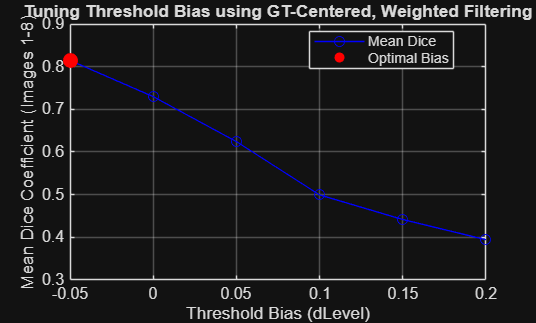


% --- Plotting the Tuning Curve ---
figure('Name', 'Threshold Bias Tuning Curve (GT-Centered, Weighted Filter)');
plot(thresholdBiases, meanDice_sweep, 'b-o');
hold on;
scatter(bestThresholdBias, bestMeanDice, 80, 'r', 'filled');
xlabel('Threshold Bias (dLevel)');
ylabel('Mean Dice Coefficient (Images 1-8)');
title('Tuning Threshold Bias using GT-Centered, Weighted Filtering');
grid on;
legend('Mean Dice', 'Optimal Bias', 'Location', 'best');
hold off;



% =======================================================
% --- 4. TESTING PHASE: Calculate Metrics for Images 9 & 10 (WITH FIXED AREA FILTER) ---
% =======================================================
fprintf('\n--- 2. Testing Phase: Applying Bias (%.2f) to Images 9 & 10 (WITH Fixed Area Filter) ---\n', bestThresholdBias);


--- 2. Testing Phase: Applying Bias (-0.05) to Images 9 & 10 (WITH Fixed Area Filter) ---


fprintf('Area Filter Range: [%d, %d] pixels\n', FIXED_MIN_AREA_TEST, FIXED_MAX_AREA_TEST);

Area Filter Range: [50000, 200000] pixels


fprintf('Image | Precision | Recall | Accuracy | Dice\n');

Image | Precision | Recall | Accuracy | Dice


fprintf('------|-----------|--------|----------|------\n');

------|-----------|--------|----------|------



masks_for_plot = cell(1, NUM_TOTAL_TEST_IMAGES);
gts_for_plot = cell(1, NUM_TOTAL_TEST_IMAGES);
test_image_indices = TEST_IMAGE_START : (TEST_IMAGE_START + NUM_TOTAL_TEST_IMAGES - 1);

for i = 1:NUM_TOTAL_TEST_IMAGES
    imgNum = test_image_indices(i);
    
    % isTraining is false for this phase (triggers the FIXED Area Filter path)
    [P, R, D, A, mask, GT] = segmentImage(imgNum, bestThresholdBias, imageFolder, gtFolder, toBinaryMask, NUM_REGIONS_TO_KEEP, MIN_AREA_THRESHOLD, false, FIXED_MIN_AREA_TEST, FIXED_MAX_AREA_TEST);
    
    % Store test metrics
    P_test(i) = P;
    R_test(i) = R;
    D_test(i) = D;
    A_test(i) = A;
    
    % Store masks for plotting
    masks_for_plot{i} = mask;
    gts_for_plot{i} = GT;
    
    % Print individual result
    fprintf('%5d | %9.4f | %6.4f | %8.4f | %6.4f\n', imgNum, P, R, A, D);
end

    9 |    0.3700 | 1.0000 |   0.9591 | 0.5402
   10 |    0.3244 | 0.9720 |   0.9537 | 0.4865




% =======================================================
% --- 5. FINAL TEST REPORT SUMMARY ---
% =======================================================
P_avg = mean(P_test);
R_avg = mean(R_test);
D_avg = mean(D_test);
A_avg = mean(A_test);

fprintf('------|-----------|--------|----------|------\n');

------|-----------|--------|----------|------


fprintf('MEAN  | %9.4f | %6.4f | %8.4f | %6.4f\n', P_avg, R_avg, A_avg, D_avg);

MEAN  |    0.3472 | 0.9860 |   0.9564 | 0.5133




% =======================================================
% --- 6. VISUALIZATION PHASE (Images 9 & 10) ---
% =======================================================
fprintf('\n--- 3. Generating Visualization Plots for Images 9 & 10 ---\n');


--- 3. Generating Visualization Plots for Images 9 & 10 ---


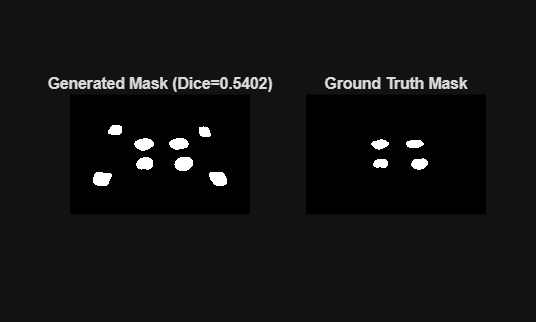

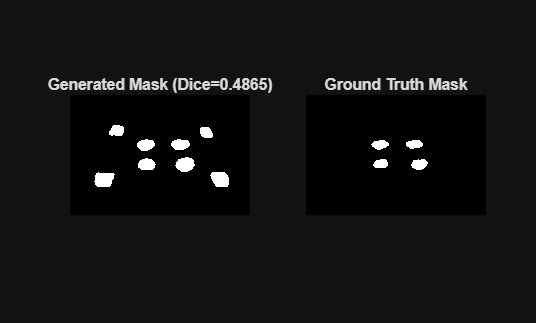


for i = 1:NUM_TOTAL_TEST_IMAGES
    imgNum = test_image_indices(i);
    D = D_test(i); 
    
    % Plotting for current image
    figure('Name', sprintf('Segmentation Results - Image %d (Dice=%.4f)', imgNum, D));
    
    % Plot Generated Mask
    subplot(1, 2, 1);
    imshow(masks_for_plot{i});
    title(sprintf('Generated Mask (Dice=%.4f)', D));
    
    % Plot Ground Truth Mask
    subplot(1, 2, 2);
    imshow(gts_for_plot{i});
    title('Ground Truth Mask');
end